## GLM Modeling of the Clustered Multielectrode Data taken with Sparse Noise Stimulus

Add project source code to the path

clear all
project_root_dir = '.';
addpath(genpath(fullfile(project_root_dir, 'src')));

### ============= Load Data =============

Import and recreate the sparse noise stimulus

config_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cjsn5x4b2.m';
configs = Config(config_file_path);
sn_stim = SparseNoiseStimulus(configs.config);

Import the timestamps for when the stimulus happened

crs_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cjsn5x4b2.ch4.crs';
stim_ts = StimTimeStamps(crs_file_path, configs.config);

WARNING!! deltimes between records in getcrs have variance >1%


Import Corresponding Spike Event Timing Data

event_timing_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\Cjsn5x4b2_clu12.txt';
spike_times = SpikeTimes(event_timing_file_path);

Compute some basic statistics on the data

dtStim = (stim_ts.tempresolu); % time bin size for stimulus (s)
RefreshRate = 1/dtStim; % Refresh rate of the monitor
nT = size(sn_stim.stimulus, 3); % number of time bins in stimulus
nsp = length(spike_times.spike_t_vector); % number of spikes
  
% Print out some basic info
fprintf('--------------------------\n');

--------------------------


fprintf('Number of stim frames: %d  (%.1f minutes)\n', nT, nT*dtStim/60);

Number of stim frames: 8192  (3.9 minutes)


fprintf('Time bin size: %.1f ms\n', dtStim*1000);

Time bin size: 28.6 ms


fprintf('Number of spikes: %d (mean rate=%.1f Hz)\n\n', nsp, nsp/nT*RefreshRate);

Number of spikes: 1673 (mean rate=7.1 Hz)



### **============= Preprocessing Data for the Model ============**

Let's bin the spike train with the stimulus timestamps.

[tbin_centers, binned_spikes] = hist_bin_spikes(stim_ts, spike_times); %compute binned spike train

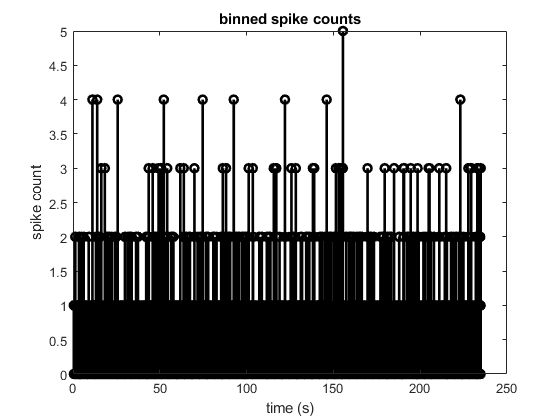

% Visualize the binned spike train
figure;
stem(tbin_centers,binned_spikes, 'k', 'linewidth', 2);
title('binned spike counts');
ylabel('spike count'); xlabel('time (s)');

Create Design Matrix

rf_temporal_len = 10; % frames
Xdsgn = make_design_matrix(sn_stim, rf_temporal_len);

dataset = DataSet(Xdsgn, binned_spikes);
train_data_pct = 0.7;
[train_var, train_lab, test_var, test_lab] = dataset.divide_train_test_data(train_data_pct);

### **=================  Plot STA  ================**

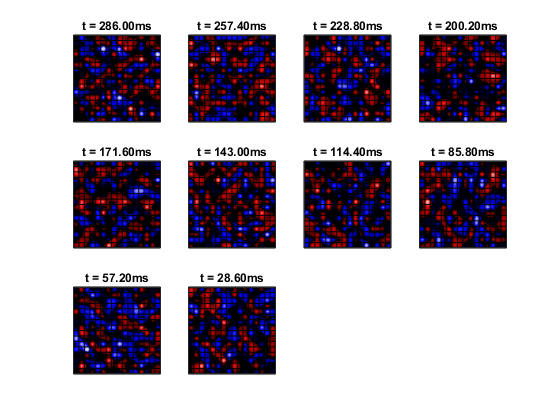

% It's extremely easy to compute the STA now that we have the design matrix
sta = (Xdsgn'*binned_spikes)/nsp;
sta = reshape(sta, [configs.config.gridsize, configs.config.gridsize, rf_temporal_len]);
plot_sta(sta, rf_temporal_len, stim_ts.tempresolu);

### **=================  Fit GLM  ================**

pGLMwts = glmfit(Xdsgn, binned_spikes, 'poisson','constant', 'on');

% plot whitened sta (weights from glm)
sta_glm = reshape(pGLMwts(2:end), [configs.config.gridsize,configs.config.gridsize,rf_temporal_len]);

The end operator must be used within an array index expression.

plot_sta(sta_glm, rf_temporal_len, stim_ts.tempresolu);

### **======  Fit Temporal-Spatial Separable Filter  ======**

defaultprs = {'Gradobj','on', 'maxiter', 1000, 'maxfunevals', 1e9, 'Display', 'iter'};
opts = optimset(defaultprs{:});
Loss = @(rf_weights) neg_log_likli_poisson(Xdsgn, binned_spikes, rf_weights, stim_ts.tempresolu, rf_temporal_len, configs.config.gridsize);
init_weight = initialize_weight_from_sta(sta, 'separable');

[loss, dL] = neg_log_likli_poisson(Xdsgn, binned_spikes, init_weight, stim_ts.tempresolu, rf_temporal_len, configs.config.gridsize);

Neg Log Likelihood: 6424.547
gradient norm length: 211.015


[weight_final,neglogli,exitflag] = fminunc(Loss,init_weight,opts);

Neg Log Likelihood: 6424.547
gradient norm length: 211.015
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          6424.55                          41.8
Neg Log Likelihood: 5569.656
gradient norm length: 192.963
     1           2          5569.66      0.0239249           72.3  
Neg Log Likelihood: 1286337697.144
gradient norm length: 6007147023.139
Neg Log Likelihood: 50785.957
gradient norm length: 96345.447
Neg Log Likelihood: 6507.566
gradient norm length: 2399.556
Neg Log Likelihood: 5499.010
gradient norm length: 181.612
     2           6          5499.01        0.10207             52  
Neg Log Likelihood: 5387.497
gradient norm length: 109.623
     3           7           5387.5              1           43.8  
Neg Log Likelihood: 5329.793
gradient norm length: 76.326
     4           8          5329.79              1           37.7  
Neg Log Likelihood: 5303.166
gradient

if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end

% plot temporal and spatial rf
temporal_rf = weight_final(1:rf_temporal_len);
spatial_rf = reshape(weight_final(rf_temporal_len+1:end), 16,16);

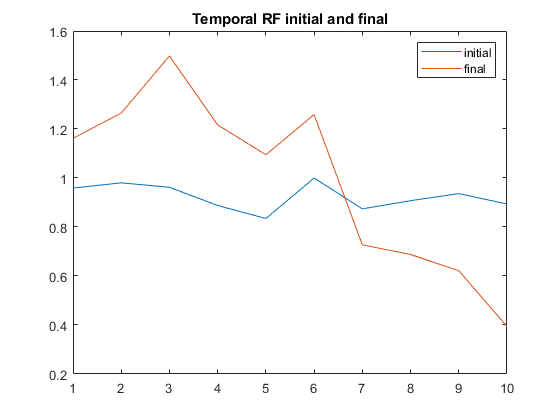

figure;
plot(init_weight(1:rf_temporal_len));
hold on;
plot(temporal_rf);
legend('initial', 'final')
title('Temporal RF initial and final')

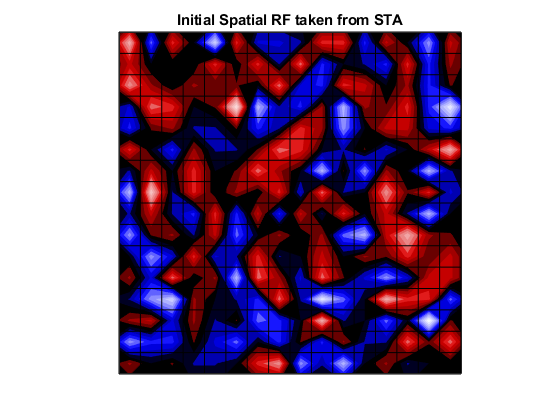

figure;

plot_sta(reshape(init_weight(rf_temporal_len+1:end),16,16), 1, 1);
title('Initial Spatial RF taken from STA')

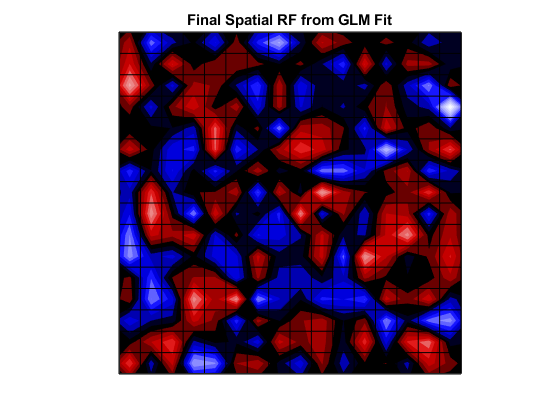

figure;
plot_sta(spatial_rf, 1, 1);
title('Final Spatial RF from GLM Fit')

### **======  Fit Temporal-Spatial + On / Off Separable Filter  ======**

defaultprs = {'Gradobj','on', 'maxiter', 1000, 'maxfunevals', 1e9, 'Display', 'iter'};
opts = optimset(defaultprs{:});
Loss = @(rf_weights) neg_log_likli_poisson(Xdsgn, binned_spikes, rf_weights, stim_ts.tempresolu, rf_temporal_len, configs.config.gridsize);;
init_weight = initialize_weight_from_sta(sta, 'separable');
spatial_rf_on = init_weight(rf_temporal_len+1:end);
spatial_rf_off = spatial_rf_on;
spatial_rf_on(spatial_rf_on<0)=0;
spatial_rf_off(spatial_rf_off>0)=0;
init_weight_onoff = [init_weight(1:rf_temporal_len); spatial_rf_on; spatial_rf_off];

[weight_final,neglogli,exitflag] = fminunc(Loss,init_weight_onoff,opts);

Neg Log Likelihood: 6415.835
gradient norm length: 622.243
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          6415.84                          60.7
Neg Log Likelihood: 18562.170
gradient norm length: 29386.691
Neg Log Likelihood: 4481.795
gradient norm length: 316.550
     1           3           4481.8     0.00823699            102  
Neg Log Likelihood: 4869.784
gradient norm length: 716.009
Neg Log Likelihood: 4440.522
gradient norm length: 128.806
     2           5          4440.52       0.208245             37  
Neg Log Likelihood: 4363.019
gradient norm length: 92.420
     3           6          4363.02              1           20.1  
Neg Log Likelihood: 4329.757
gradient norm length: 502.390
Neg Log Likelihood: 4265.430
gradient norm length: 173.568
     4           8          4265.43       0.606777           57.5  
Neg Log Likelihood: 4229.522
gradient norm length: 

if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end

% plot temporal and spatial rf
temporal_rf_onoff = weight_final(1:rf_temporal_len);
spatial_rf_on = reshape(weight_final(rf_temporal_len+1:rf_temporal_len+16^2), 16,16);
spatial_rf_off = reshape(weight_final(rf_temporal_len+16^2+1:end), 16,16);

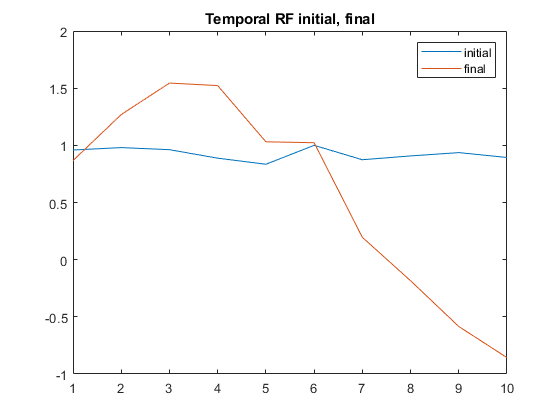

figure;
plot(init_weight_onoff(1:rf_temporal_len));
hold on;
plot(temporal_rf_onoff);
legend('initial', 'final')
title('Temporal RF initial, final')

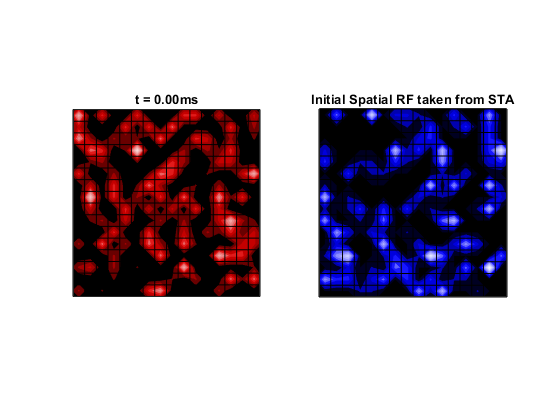

figure;
plot_sta(reshape(init_weight_onoff(rf_temporal_len+1:end),16,16,2), 2, 0);
title('Initial Spatial RF taken from STA')

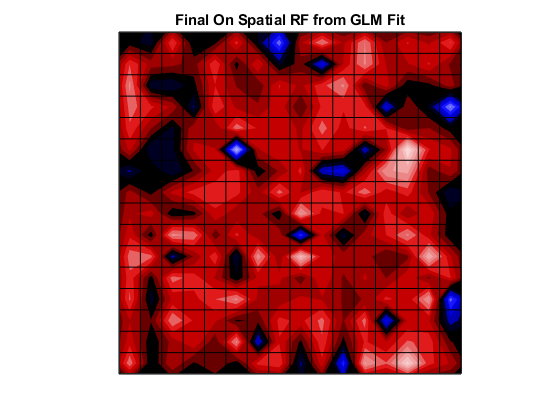

figure;
plot_sta(spatial_rf_on, 1, 0);
title('Final On Spatial RF from GLM Fit')

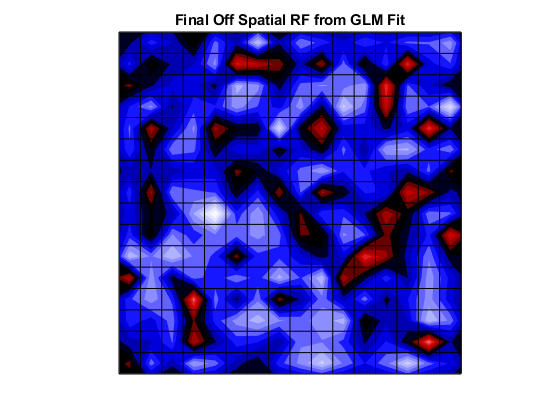

figure;
plot_sta(spatial_rf_off, 1, 0);
title('Final Off Spatial RF from GLM Fit')